a = 1 + mod(137,3);

%Q1)
Rp = a;
Rs = 40;
fs = 720;
wp = 10/(720/2);
ws = 20/(720/2); 

[n,wn] = buttord(wp,ws,Rp,Rs);
[b,a] = butter(n,wn);

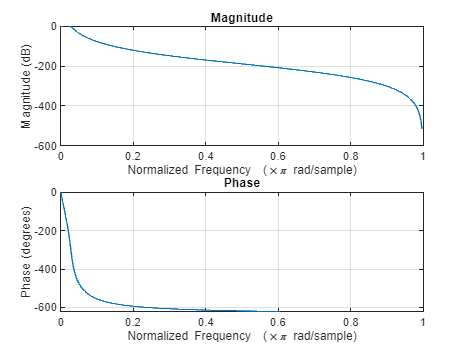

freqz(b,a,fs/2)

%1)
H = tf(b,a,1/fs)

H =
 
                                                                                                
  3.201e-10 z^7 + 2.241e-09 z^6 + 6.722e-09 z^5 + 1.12e-08 z^4 + 1.12e-08 z^3 + 6.722e          
                                                                                                
                                                               -09 z^2 + 2.241e-09 z + 3.201e-10
                                                                                                
  ----------------------------------------------------------------------------------------------
                                                                                         
        z^7 - 6.593 z^6 + 18.64 z^5 - 29.3 z^4 + 27.64 z^3 - 15.66 z^2 + 4.929 z - 0.6655
                                                                                         
 
Sample time: 0.0013889 seconds
Discrete-time transfer function.



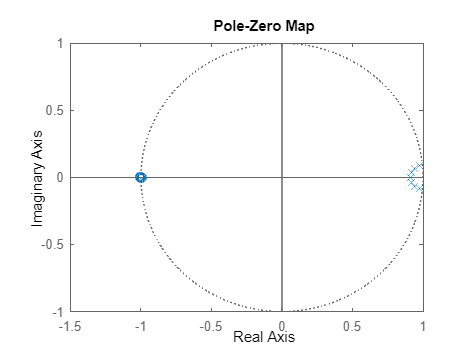

%2)
figure;
pzmap(H);

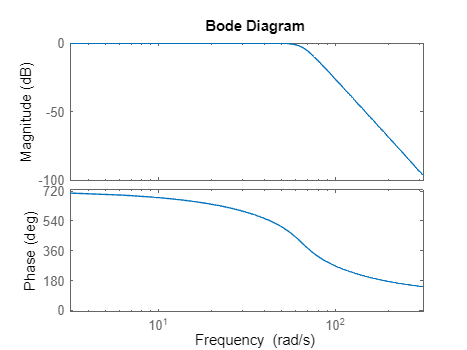

%3)
figure;
flin = linspace(0,50,100);
bode(H, 2*pi.*flin);

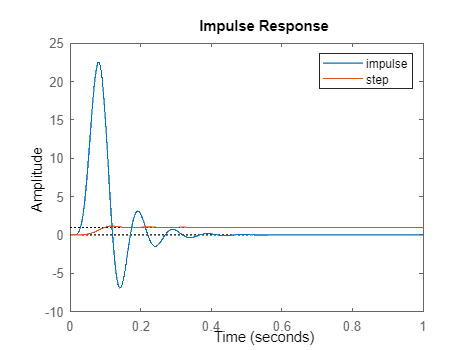

figure;
impulse(H,1);
hold on;
step(H,1);
legend('impulse', 'step')
hold off;

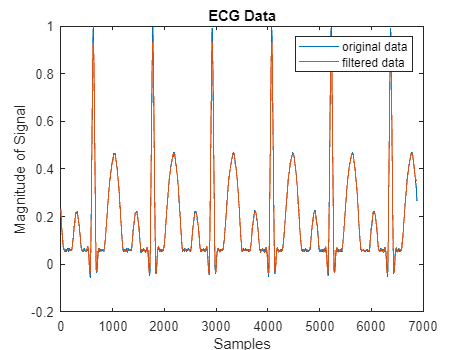

%Q2)
data = importdata('ECG_Data.txt');
Fs = 720;
plot(data);
filt_data = filtfilt(b,a,data);
hold on;
plot(filt_data);
legend('original data', 'filtered data');
title('ECG Data');
xlabel('Samples')
ylabel('Magnitude of Signal')
hold off;

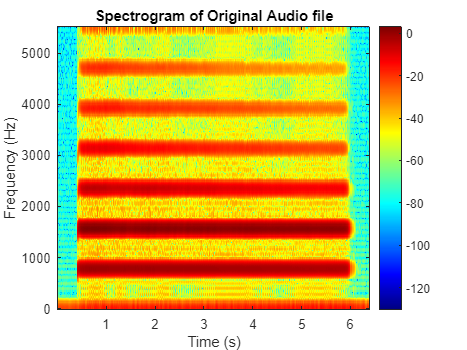

%Q3)
%Spectrogram
figure;
% Step 1: Read the audio file
audioFilePath = 'instru3.wav';  % Replace with the path to your audio file
[y, fs] = audioread(audioFilePath);

% Step 2: Define spectrogram parameters
windowSize = 100;  % Size of the analysis window (e.g., 256 samples)
overlap = 10;     % Overlap between consecutive windows (e.g., 50% overlap)
nfft = 512;        % Number of FFT points (higher values give finer frequency resolution)

% Step 3: Compute the spectrogram
[S, F, T] = spectrogram(y, hamming(windowSize), overlap,nfft,fs);

% Step 4: Plot the spectrogram
figure;
imagesc(T, F, 20*log10(abs(S)));  % Convert to dB scale
axis xy;  % Flip the y-axis to have lower frequencies at the bottom
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Original Audio file');
colorbar;  % Display a colorbar showing the magnitude in dB
colormap('jet');

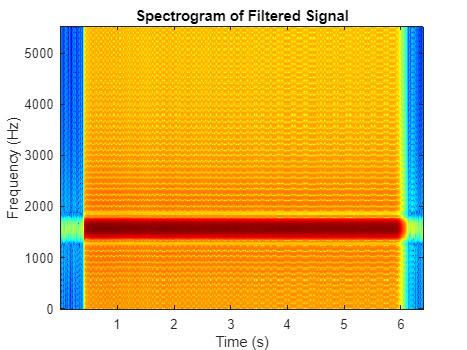

% Design a Butterworth bandpass filter
low_cutoff = 1500;  % Lower cutoff frequency in Hz
high_cutoff = 1600;  % Upper cutoff frequency in Hz
order = 4;  % Filter order

[b, a] = butter(order, [low_cutoff, high_cutoff] / (fs / 2), 'bandpass');

% Apply the filter to extract the fundamental frequency
filtered_signal = filter(b, a, y);

% Write the filtered signal to a new WAV file
audiowrite('filtered_instru3.wav', filtered_signal, fs);

% Listen to the filtered audio
%sound(filtered_signal, fs);

% Compute and plot the spectrogram of the filtered signal
[S_filtered, F_filtered, T_filtered] = spectrogram(filtered_signal, hamming(windowSize), overlap, nfft, fs);

figure;
imagesc(T_filtered, F_filtered, 20*log10(abs(S_filtered)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Filtered Signal');
colormap('jet');

%Q4)
[ n2 , wp ] = cheb1ord(wp,ws,Rp,Rs);
[b2,a2] = cheby1(n2,Rp,wp);
H2 = tf(b2,a2,1/fs)

H2 =
 
  9.671e-09 z^5 + 4.835e-08 z^4 + 9.671e-08 z^3 + 9.671e-08 z^2 + 4.835e-08 z + 9.671e-09
  ---------------------------------------------------------------------------------------
                 z^5 - 4.94 z^4 + 9.773 z^3 - 9.675 z^2 + 4.794 z - 0.9511
 
Sample time: 0.0013889 seconds
Discrete-time transfer function.



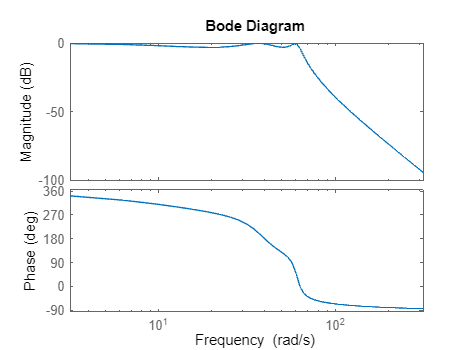

figure;
flin = linspace(0,50,100);
bode(H2, 2*pi.*flin);

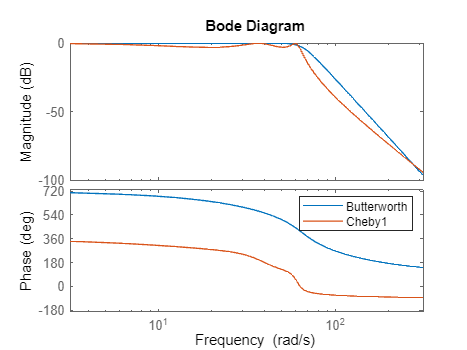

figure;
bode(H, 2*pi.*flin);
hold on;
bode(H2, 2*pi.*flin);
legend('Butterworth','Cheby1');
hold off

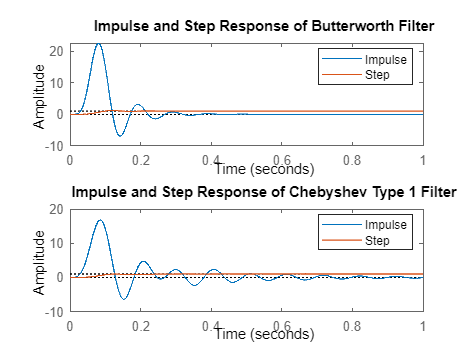

figure;
subplot(2,1,1)
impulse(H,1)
hold on 
step(H,1)
hold off
title('Impulse and Step Response of Butterworth Filter')
legend('Impulse','Step')

subplot(2,1,2)
impulse(H2,1)
hold on
step(H2,1)
hold off
title('Impulse and Step Response of Chebyshev Type 1 Filter')
legend('Impulse','Step')